## Initialize

fs = 1000;
ts = 1/fs;
set(0,'defaultlinelinewidth',3);
set(0,'defaultaxesfontsize',22);

Vref = data(:,3);
Vfeedback = data(:,1);
Vcontrol = data(:,2);

## Example 3 Demo

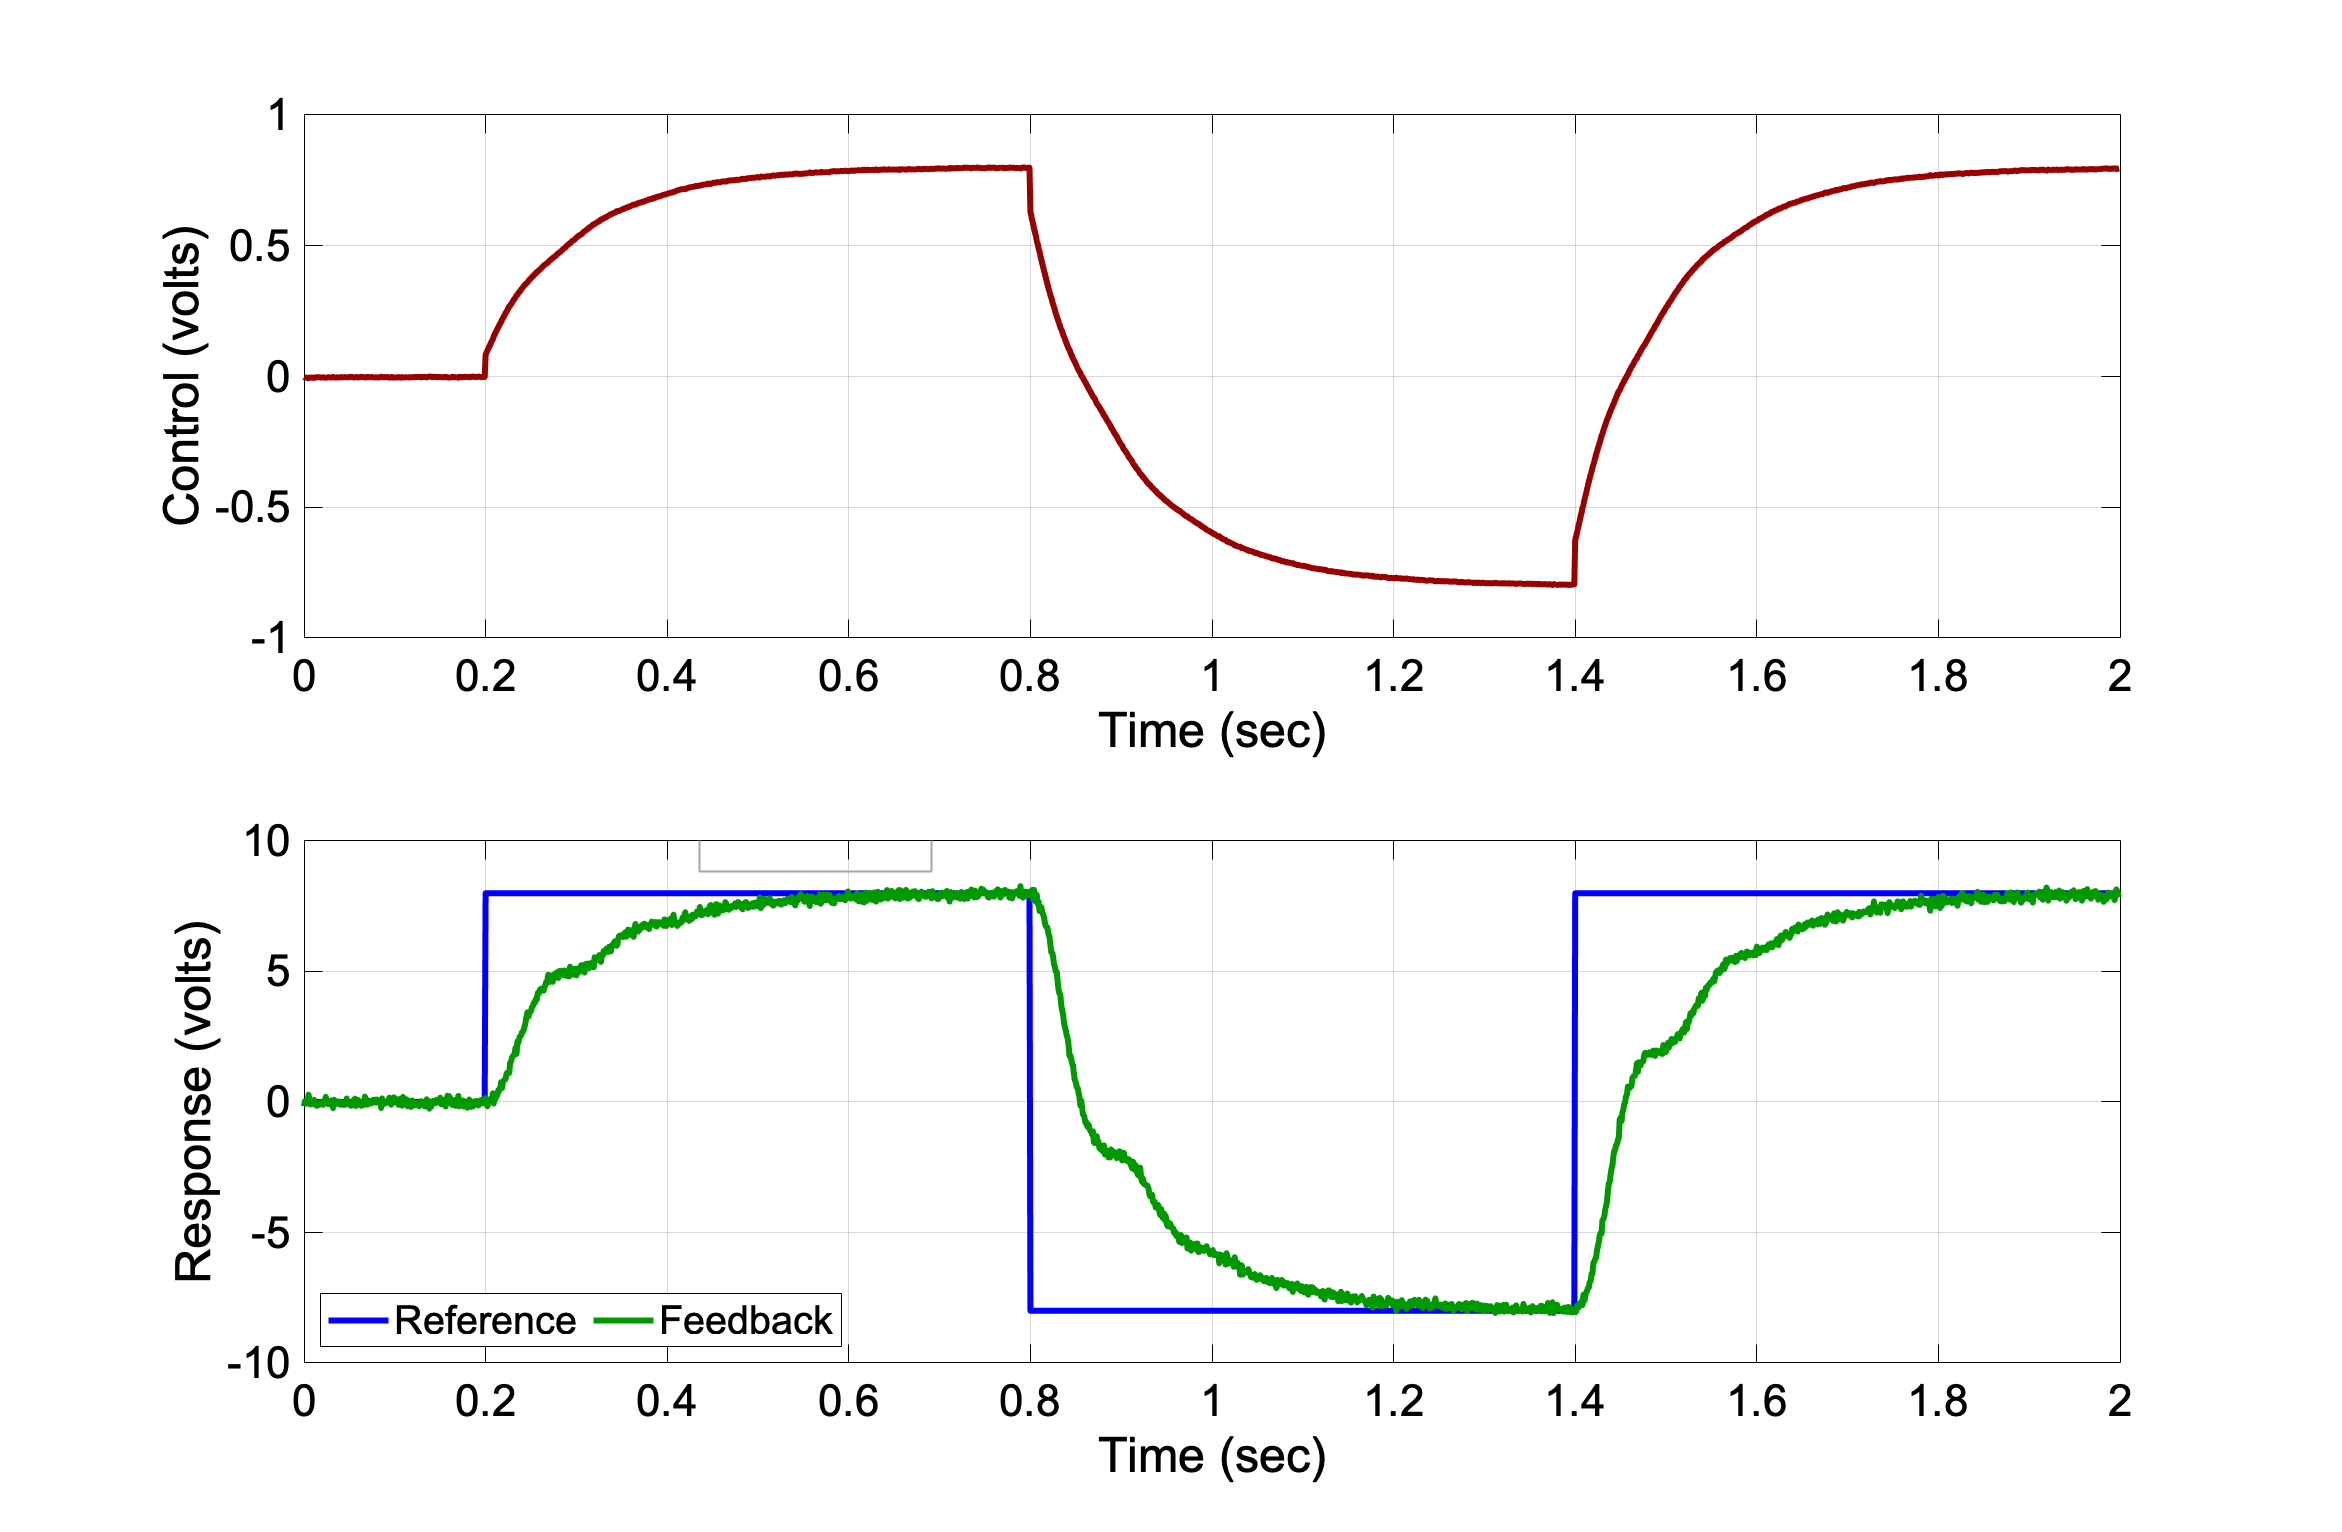

N = size(data,1);
t = ts*[0:N-1];

figure
clf
subplot(2,1,1);
plot(t,Vcontrol,'color',[0.6 0 0])
ylabel('Control (volts)')
xlabel('Time (sec)')
grid on
ylim(1*[-1,1])

subplot(2,1,2);
plot(t,Vref,'b')
hold on
plot(t,Vfeedback,'color',[0 0.6 0])
ylabel('Response (volts)')
xlabel('Time (sec)')
legend('Reference','Feedback','orientation','horizontal', ...
    'location','southwest')
grid on
ylim(10*[-1,1])